# Example - Zeeman Map

clear all
addpath("Molecules\");addpath("Atoms\")
C = Constants;
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesBox','on')
set(groot,'defaultAxesLineWidth',0.5)

## Define Fields

maxN = 1;
B.value = [1e-6:0.5:20];
B.dir = [0,0,1];
B.scaling = 1e-4; %put B.value in Gauss, not Tesla
E.value = [0]; %V/m
E.dir = [0,0,1];
E.scaling = 1e2;%put E.value in V/cm, not V/m
I.value = [0];
I.dir = [0,0,1];
I.pol = [1,0,0];
I.scaling = 1e7;%put I.value in mW/cm^2, not W/m^2
Fields.B = B;
Fields.E = E;
Fields.I = I;

## Define Hamiltonian

Mol = KRb(40,87);
Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
H0 = Ham.hyperfine.total + I.value*I.scaling*Ham.ac_stark + E.value*E.scaling*Ham.dc_stark;
Base = Ham.Basis;
nStates = Base.NStates;

## Diagonalise for varying intensity

F = B;
x = F.value;
energyMap = nan(length(x),nStates);
statesMap = nan(length(x),nStates,nStates);
for k = 1:length(x)
    if mod(k,10)==1; fprintf("%d - ",k); end
    H = H0 + x(k)*F.scaling*Ham.zeeman;
    [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
    [d,sortIdx] = sort(real(D));
    energyMap(k,:)=d;        
    statesMap(k,:,:) = V(:,sortIdx);
end

1 - 11 - 21 - 31 - 

disp("Finished")

Finished


## Plot Results

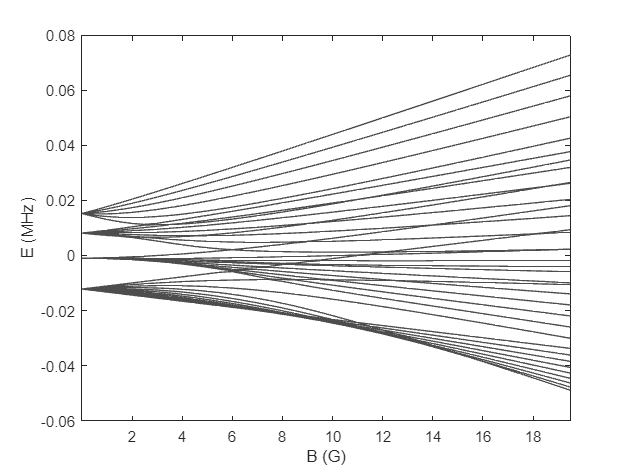

N = Base.getStates("N");
figure(13); clf;
plot(x,energyMap(:,N==0)*1e-6, color=[1,1,1]*0.3); hold on;
xlabel("B (G)")
ylabel(sprintf("E (MHz)"))
% ylim([-1.5,1])
xlim([min(x),max(x)])
grid off

## Induced Magnetic Moment